# Example Collection On Trajectories

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

We can look at a 3D Simscape™ Multibody™ model of a Quadcopter that delivers a package from one point to another. The next challenge is to create a trajectory of points between the starting and ending positions.

In general, for many robotics and autonomous systems applications, we can use [splines](https://www.mathworks.com/matlabcentral/fileexchange/111490-numerical-methods-with-applications/files/Scripts/Interpolation.mlx) to generate smooth curves between waypoints that a robot can follow. Recall that [jerk](https://en.wikipedia.org/wiki/Jerk_(physics)) is the rate of change of an object's acceleration over time. Given a position function $\mathbf{p}(t)$ which defines the location in space of our UAV at time $t$:


$$\matrix{&&\cr \hline \textbf{Name} & \textbf{Formula} & \textbf{Description} \cr \hline \text{Position} & \mathbf{p}(t) & \text{location in space} \cr \text{Velocity} & \frac{d\mathbf{p}}{dt} & \text{speed and direction} \cr \text{Acceleration} & \frac{d^2\mathbf{p}}{dt^2} & \text{rate of change of speed and direction} \cr \text{Jerk} & \frac{d^3\mathbf{p}}{dt^3} & \text{rate of change of acceleration} \cr \text{Snap} & \frac{d^4\mathbf{p}}{dt^4} & \text{rate of change of jerk}}$$


Minimizing the jerk (and other higher-order derivatives) results in a smoother ride. 

  **Try**. Run the code below to explore B-spline trajectories for waypoints. What happens when you change, add, or remove waypoints? 

% Waypoints (each column is a point in 2D)
wpts = [0  0  2  1;   % x coordinates
        0  1  1  0];  % y coordinates
 

The local function `ComputeAndPlotTrajectory` is defined at the end of this script. 

[q,qd,qdd,tvec] = ComputeAndPlotTrajectory(wpts);

Compute and plot the velocity, acceleration, and jerk of the trajectory. Ignore the fact that at the beginning and end of the trajectory there is an abrupt jump from being stopped to being in motion. 

The local function `PlotDerivatives` is defined at the end of the script. Set `UseComputedValues` to true to use the velocity and acceleration vectors returned by the built-in `bsplinepolytraj` function. When `UseComputedValues` is false, the velocity and acceleration are numerically computed from the points of the trajectory using `diff`.

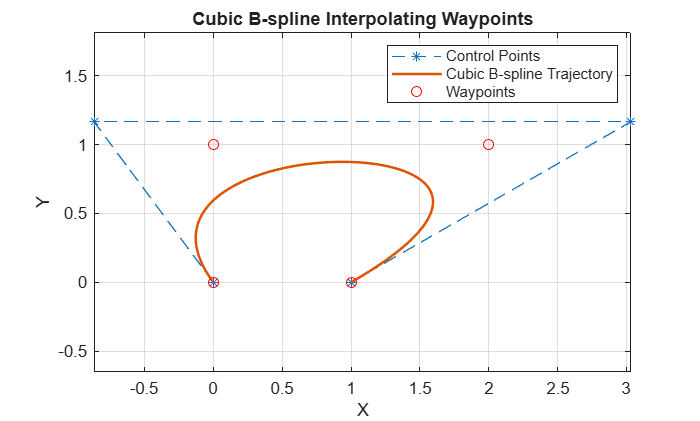

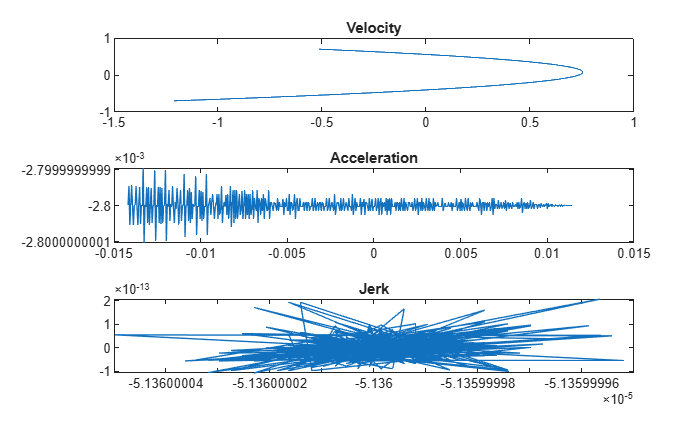

UseComputedValues = false;
PlotDerivatives(UseComputedValues,q,qd,qdd,tvec);

Each example will open in a new tab and switch to a new file location. When you are done exploring the example, close the files that were opened, return to this script, and click the "Return Here" button. This will reset your file location to the root folder for this content collection.

ReturnHere
 

## B-Spline Trajectories

For more details on the `bsplinepolytraj` function, you can read the [documentation](https://www.mathworks.com/help/robotics/ref/bsplinepolytraj.html) or open another example of its use. 

openExample("robotics/ComputeBSplineTrajectoryFor2DPlanarMotionExample")
 

ReturnHere
 

## Generate Minimum Jerk Trajectory Example

An example is given here for **Minimum Jerk Trajectories** to minimize the abrupt changes in acceleration experienced by the system.

openExample('shared_uav_robotics/GenerateMinimumJerkTrajectoryExample')
 

Open the scopes, dock them using the   icon, and display them as a grid so you can follow all the output at once. Then run the simulation.

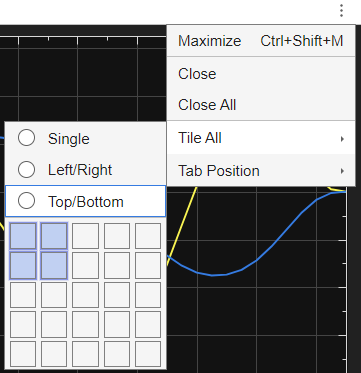

ReturnHere
 

## Package Delivery Quadcopter Example

Simscape Multibody provides tools for designing, simulating, and testing robotic systems, such as manipulators, humanoid robots, and drones. The **Package Delivery Quadcopter Example** simulates a complete flight by a package delivery drone.

openExample('sm/QuadcopterExample')
 

ReturnHere
 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Details of the `ComputeAndPlotTrajectory` function.  $\uparrow$Return to text

function [q, qd, qdd, tvec] = ComputeAndPlotTrajectory(wpts)
L = size(wpts,2) - 1;            % number of spline segments

% Build linear system A * dInterior = r to compute interior control points
% See standard construction for cubic B-spline interpolation
A = eye(L+1);
r = zeros(L+1, size(wpts,1));

% Fill interior rows
for i = 1:(L-1)
    A(i+1, i:(i+2)) = [1 4 1];
    r(i+1,:) = 6 * wpts(:,i+1)';      % note transpose to row
end

% Boundary rows (end conditions for cubic interpolation)
A(2,1:3)      = [3/2 7/2 1];
A(L, (L-1):(L+1)) = [1 7/2 3/2];

% Right-hand side for boundaries
r(1,:)   = (wpts(:,1) + (wpts(:,2) - wpts(:,1))/2)';   % r0
r(end,:) = (wpts(:,end-1) + (wpts(:,end) - wpts(:,end-1))/2)'; % rL

% Solve for the complete control polygon (columns are control pts)
dInterior = (A \ r)';                 % returns (2 x (L+1)) then transpose
cpts = [wpts(:,1), dInterior(:,2:end-1), wpts(:,end)]; % 2 x (nCtrlPts)

% Time vector and trajectory generation (piecewise cubic)
t0 = 0; tf = 5;
tvec = linspace(t0, tf, 501);
[q, qd, qdd, ~] = bsplinepolytraj(cpts, [t0 tf], tvec);

% Plot control points and resulting spline trajectory
figure
plot(cpts(1,:), cpts(2,:), '*--', 'DisplayName','Control Points') 
hold on
plot(q(1,:), q(2,:), 'LineWidth',1.5, 'DisplayName','Cubic B-spline Trajectory');
plot(wpts(1,:), wpts(2,:), 'ro', 'DisplayName','Waypoints');
hold off
legend
axis equal 
grid on
xlabel("X") 
ylabel("Y") 
title("Cubic B-spline Interpolating Waypoints")
end

Details of the `PlotDerivatives` function       $\uparrow$ Return to text

function PlotDerivatives(UseComputedValues,q,qd,qdd,tvec)
tiledlayout(3,1);
if UseComputedValues
    TrajVel = qd(:,1:end-1);
    TrajAcc = qdd(:,1:end-1);
    TrajJerk = diff(TrajAcc,1,2)./diff(tvec(:,1:end-1),1);
else
    TrajVel = diff(q,1,2)./diff(tvec,1);
    TrajAcc = diff(q,2,2)./diff(tvec(:,1:end-1),1);
    TrajJerk = diff(q,3,2)./diff(tvec(:,1:end-2),1);
end

nexttile
plot(TrajVel(1,:),TrajVel(2,:))
title("Velocity")
nexttile
plot(TrajAcc(1,:),TrajAcc(2,:))
title("Acceleration")
nexttile
plot(TrajJerk(1,:),TrajJerk(2,:))
title("Jerk")
end

function ReturnHere()
curloc = matlab.desktop.editor.getActiveFilename;
if contains(curloc,"Scripts")
    rootdir = extractBefore(curloc,filesep+"Scripts");
elseif contains(curloc,"InstructorResources")
    rootdir = extractBefore(curloc,filesep+"InstructorResources");
else
    error("Unexpected location: " + curloc)
end
cd(rootdir)
end